% Declaring the values of system variables
% M is the Mass of cart
% m1 is the mass attached to pendulum 1
% m2 is the mass attached to pendulum 2
% l1 is the length of pendulum 1
% l2 is the length of pendulum 2
% g is the accleration due to gravity 
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;

% Defining the Q and R matrices for LQR controller
Q = [100  0  0  0  0  0;
     0  0  0  0  0  0;
     0   0 1000 0  0  0;
     0   0  0  0  0  0;
     0   0  0  0 1000 0;
     0   0  0  0  0  0];

R = 0.001;

% Declaring the A matrix of the system
A_val = [0 1 0 0 0 0;
         0 0 -(m1_val*9.81)/M_val 0 -(m2_val*9.81)/M_val 0;
         0 0 0 1 0 0;
         0 0 -((M_val+m1_val)*9.81/(M_val*l1_val)) 0 -(m2_val*9.81)/(M_val*l1_val) 0;
         0 0 0 0 0 1;
         0 0 -(m1_val*9.81)/(M_val*l2_val) 0 -((M_val+m2_val)*9.81/(M_val*l2_val)) 0];

% Declaring the B matrix of the system
B_val = [0; 1/M_val; 0; 1/(M_val*l1_val); 0; 1/(M_val*l2_val)];


% Finding the optimal feedback gain K for the above LQR controller
[K, R_soln, poles] = lqr(A_val,B_val,Q,R);

% The controllability matrix when output vector is x(t)
C1 = [1 0 0 0 0 0];

% The controllability matrix when output vector is (theta1(t), theta2(t))
C2 = [0 0 1 0 0 0;
      0 0 0 0 1 0];

% The controllability matrix when output vector is (x(t), theta2(t))
C3 = [1 0 0 0 0 0;
      0 0 0 0 1 0];

% The controllability matrix when output vector is (x(t), theta1(t), theta2(t))
C4 = [1 0 0 0 0 0;
      0 0 1 0 0 0;
      0 0 0 0 1 0];

% For the A matrix after putting parameter values
ob1 = obsv(A_val, C1);
ob2 = obsv(A_val, C2);
ob3 = obsv(A_val, C3);
ob4 = obsv(A_val, C4);

% The poles of the Luenberger observer
L_poles = [-4; -4.5; -5; -5.5; -6; -6.5];
% Specifying the initial condition where estimated states 
% are initialized to zero
x0 = [0;0;0.5;0;0.6;0;0;0;0;0;0;0];

% The observer gains for each observer, when the observer poles are placed
% at L_poles
L1 = place(A_val', C1', L_poles);
L3 = place(A_val', C3', L_poles);
L4 = place(A_val', C4', L_poles);

% Luenberger A matrix for first observer
A_c1 = [(A_val - B_val*K) B_val*K ; zeros(size(A_val)) (A_val - (L1'*C1))];
% Luenberger B matrix for first observer
B_c1 = [B_val; B_val];
% Luenberger C and D matrix for first observer
C_c1 = [C1 zeros(size(C1))];
D1 = 0;

% Checking the response of system when x(t) is observed
sys_ob1 = ss(A_c1, B_c1, C_c1, D1);

% The Luenberger observer obtained when x(t) is observed
disp("The Luenberger observer of the system when x(t) is observed ")

The Luenberger observer of the system when x(t) is observed 


disp(L1);

   1.0e+04 *

    0.0031    0.0410   -4.4234   -2.9057    4.1383    1.8485



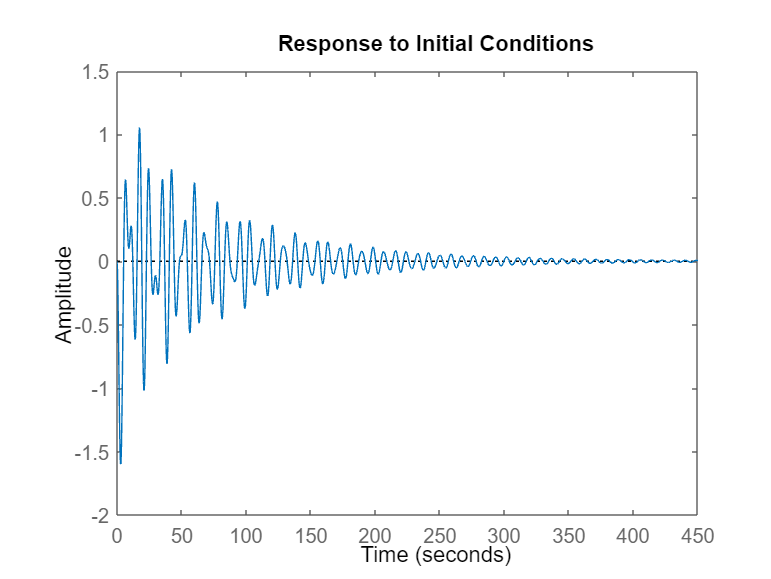


% The response of linearized system to initial conditions 
% theta1 = 0.5 radians and theta2 = 0.6 radians
initial(sys_ob1, x0)

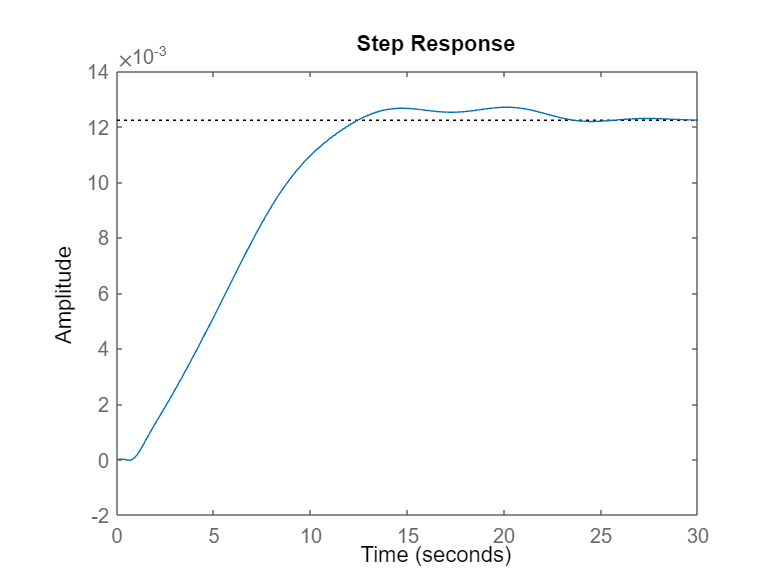

% Response of system when unit step is given as input
step(sys_ob1)







% The Luenberger observer of the system when x(t) and 
% theta2(t) are observed 
disp("The Luenberger observer of the system when x(t) and theta2(t) are observed ")

The Luenberger observer of the system when x(t) and theta2(t) are observed 


disp(L3);

   1.0e+03 *

    0.0192    0.1352   -0.4165   -0.4116    0.0009    0.0108
    0.0158    0.2445   -1.2641   -1.9875    0.0123    0.0519



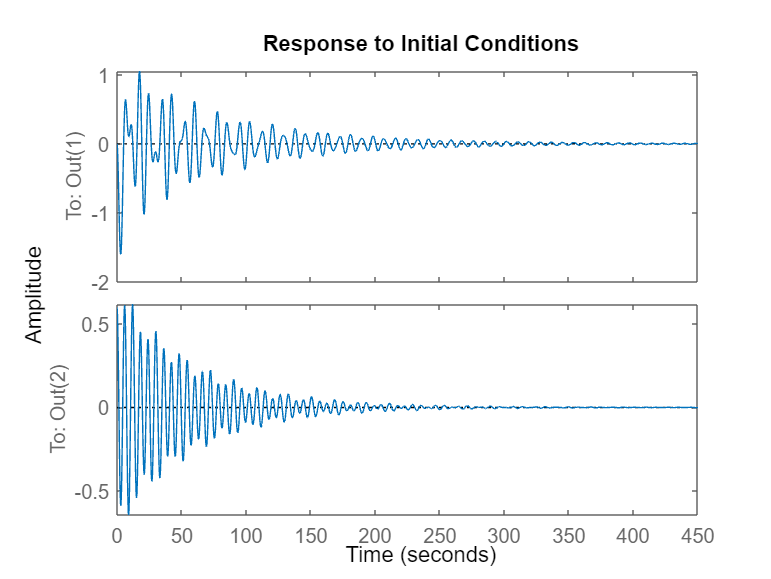


% Luenberger A matrix for third observer
A_c3 = [(A_val - B_val*K) B_val*K ; zeros(size(A_val)) (A_val - (L3'*C3))];
% Luenberger B matrix for third observer
B_c3 = [B_val; B_val];
% Luenberger C and D matrix for third observer
C_c3 = [C3 zeros(size(C3))];
D3 = 0;

% Checking the response of system when x(t) and 
% theta2(t) are observed 
sys_ob3 = ss(A_c3, B_c3, C_c3, D3);

% The response of linearized system to initial conditions 
% theta1 = 0.5 radians and theta2 = 0.6 radians
initial(sys_ob3, x0)

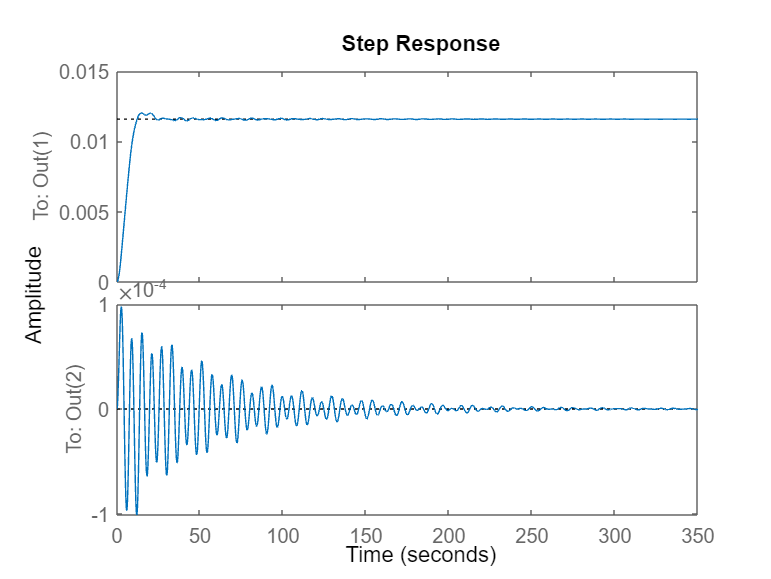

% Response of system when unit step is given as input
step(sys_ob3)




% The Luenberger observer of the system when x(t), 
% theta1(t) and theta2(t) are observed 
disp("The Luenberger observer of the system when x(t), theta1(t) and theta2(t) are observed ")

The Luenberger observer of the system when x(t), theta1(t) and theta2(t) are observed 


disp(L4);

   11.5848   33.3556    0.5072    2.9226    0.0000    0.0000
    0.4784    1.7664   11.4152   31.8547    0.0000   -0.0981
    0.0000   -0.9809    0.0000   -0.0489    8.5000   16.9209



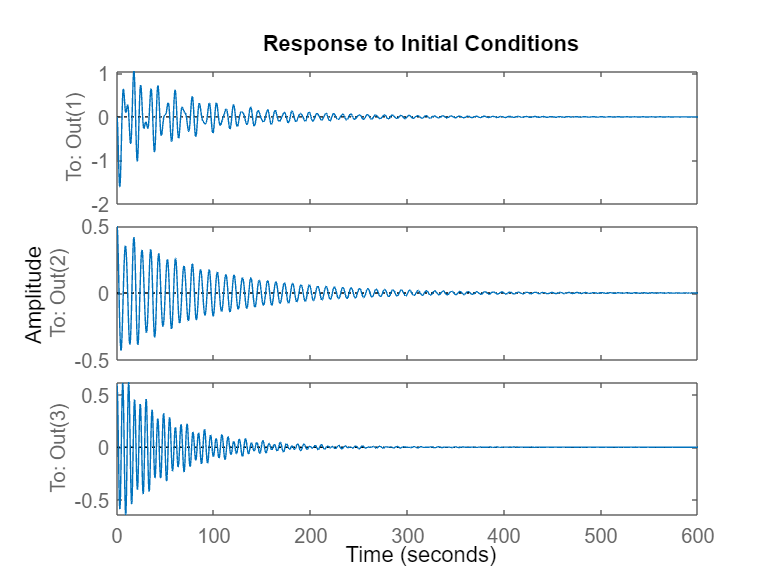


% Luenberger A matrix for fourth observer
A_c4 = [(A_val - B_val*K) B_val*K ; zeros(size(A_val)) (A_val - (L4'*C4))];
% Luenberger B matrix for fourth observer
B_c4 = [B_val; B_val];
% Luenberger C and D matrix for fourth observer
C_c4 = [C4 zeros(size(C4))];
D4 = 0;

% Checking the response of system when x(t), theta1(t) and 
% theta2(t) are observed
sys_ob4 = ss(A_c4, B_c4, C_c4, D4);

% The response of linearized system to initial conditions 
% theta1 = 0.5 radians and theta2 = 0.6 radians
initial(sys_ob4, x0)

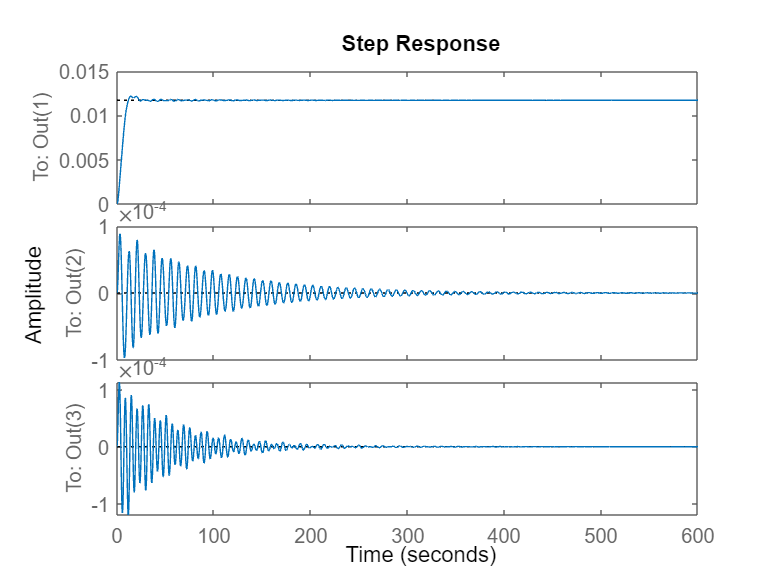

% Response of system when unit step is given as input
step(sys_ob4)